clear;clc;close all;

## Initialization

% Define start and stop times, set an h to keep outputs at constant time
% interval. You should only change h for different requirements.
t = 0;
tfinal = 3;
h = 0.04; % seconds
tspan = t:h:tfinal;

% Initialize state and contact mode
q = [0.2;1];
% q = [0.2; 0.3891];
dq = [0;0];
% dq = [0;-9.3887];

% Initialize arrays for logging data
xout = []; % collection of state vectors at each time
lambdaout = []; % collection of contact forces at each time

% Initialize contact mode
oldContactMode = zeros(0,1);
disp(['Initialize in mode {', num2str(oldContactMode'), '}.']);

Initialize in mode {}.


## Main Loop

%Initializing variables
syms x y dx dy lambda_1 lambda_2 real% m g h x0 y0 dx0 dy0 real

q_ii = [x;y];
dq_ii = [dx;dy];
lambda_ii = [lambda_1;lambda_2];

%Dynamics
m = 1;
g = 9.8;
M = [m 0; 0 m];
N = [0; m*g*y];
input = [0; 0];

%Constraints
a = [2*y + x; 2*y - x];
A = jacobian(a,q_ii);

xout = [q;dq]';
% xout = [x0;y0;dx0;dy0]';
lambdaout = [0;0]';


for i = 1:length(tspan)
    
    q_i = q;
    dq_i = dq;

    % Solve for new state and contact forces
    eqn1 = M*(dq_ii - dq_i) + h*N + A'*lambda_ii == 0;
    eqn4 = q_ii == q_i + h*(dq_ii);
    eqn5 = a >= 0;
    eqn6 = -lambda_1 >= 0;
    eqn7 = -lambda_2 >= 0;
    eqn2 = -a.*lambda_ii == 0;
    
    [x_new,y_new,dx_new,dy_new,lambda_1_new,lambda_2_new,] = solve(eqn1,eqn2,eqn4,eqn5,eqn6,eqn7,[q_ii;dq_ii;lambda_ii]);
 

    % Log state and contact forces
    xout = [xout; double([x_new;y_new;dx_new;dy_new]')];
    lambdaout = [lambdaout; double([lambda_1_new lambda_2_new])];
    

    % Check new contact mode and determine if there has been a transition
    currContactMode = [];
    if double(lambda_1_new) > 0
        currContactMode = [currContactMode 1];
    end
    if double(lambda_2_new) > 0
        currContactMode = [currContactMode 2];
    end
    
    if currContactMode ~= oldContactMode
        disp(['Transition from mode {', num2str(currContactMode), '} to mode {', num2str(currContactMode), '} at t = ', num2str(tspan(i)), '.']);
    end


    % Reset data
    q = double([x_new;y_new]);
    dq = double([dx_new;dy_new]);
end


currContactMode = [];
if double(lambdaout(end,1)) > 0
    currContactMode = [currContactMode 1];
end
if double(lambdaout(end,2)) > 0
    currContactMode = [currContactMode 2];
end

disp(['Terminate in mode {', num2str(currContactMode), '} at t = ', num2str(tspan(end)), '.']);

Terminate in mode {} at t = 3.


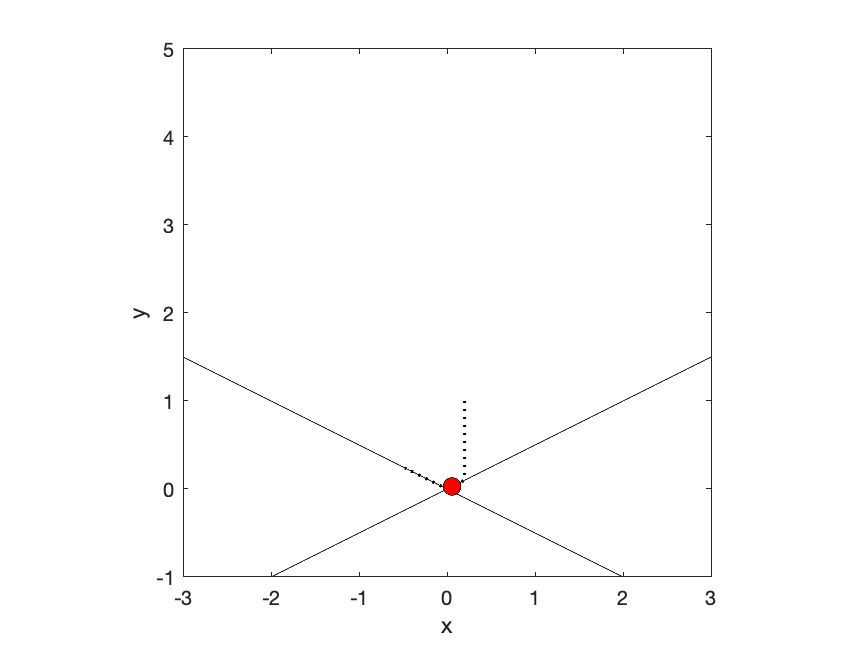


% This function shows animation for the simulation, don't modify it
animateHW12(xout, h);